clc, clearvars;
dsConcrete = imageDatastore("/home/kheyal/Documents/Computer-Vision/ComputerVisionData/Concrete", "IncludeSubfolders",true, "LabelSource","foldernames");
dsConcrete.Labels = renamecats(dsConcrete.Labels, ["No Crack" "Crack"]);
categories(dsConcrete.Labels)

ans = 2×1 cell array
    {'No Crack'}
    {'Crack'   }


[dsTrain, dsTest] = splitEachLabel(dsConcrete, 0.8, "randomized");

intensityAvg = [];
intensityStd = [];
imgName = [];

while hasdata(dsTrain)

    [img, info] = read(dsTrain);
    
    img = im2double(img);
    img = im2gray(img);
    
    intensityAvg = [intensityAvg; mean(img(:))];
    intensityStd = [intensityStd; std(img(:))];
    
    [~, name, ext] = fileparts(info.Filename);
    imgName = [imgName; string(name) + string(ext)];

end

label = categorical(dsTrain.Labels);
concreteTable = table(label, imgName, intensityAvg, intensityStd)

concreteTable = 800×4 table
     label        imgName      intensityAvg    intensityStd
    ________    ___________    ____________    ____________

    No Crack    "00044.jpg"      0.77811         0.023076  
    No Crack    "00045.jpg"      0.68332         0.030218  
    No Crack    "00188.jpg"      0.75051         0.045049  
    No Crack    "00268.jpg"      0.75853          0.05298  
    No Crack    "00272.jpg"      0.78788         0.025274  
    No Crack    "00312.jpg"      0.82332         0.047729  
    No Crack    "00313.jpg"      0.62155          0.03279  
    No Crack    "00332.jpg"      0.81527         0.027192  
    No Crack    "00422.jpg"      0.77582         0.044448  
    No Crack    "00486.jpg"      0.64485        0.0096845  
    No Crack    "00547.jpg"      0.67598         0.026524  
    No Crack    "00582.jpg"      0.74048         0.0279

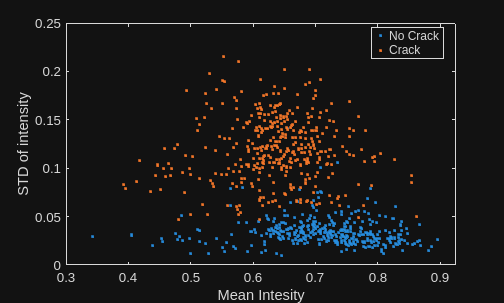

gscatter(concreteTable.intensityAvg, concreteTable.intensityStd, concreteTable.label);
xlabel("Mean Intesity");
ylabel("STD of intensity");